# Eigen-Decomposition & Singular Value Decomposition

Note that the costs of eigen-decomposition and SVD are as

- $9n^3$ if matrix is with size $n\times n$

- $14mn^2+8n^3$ if matrix is with size $m\times n ~ (m\geq n)$  

Please refer to Nicholas J. Higham, *Functions of Matrices: Theory and Computation* for more detail.

## Fix matrix

The **symmetric **matrix is used.

clc; clear; close all;
addpath('../data')

matrix_size = 200;
sparse_ratio = 0.7;

X = normrnd(0, 1, matrix_size, matrix_size);
X = X+X'; % symmetrization
tmp = quantile(abs(X(:)), sparse_ratio);
X(abs(X)<tmp) = 0.0;
disp('The left-top 5-by-5 sub-matrix:')

The left-top 5-by-5 sub-matrix:


disp(X(1:5, 1:5))

   -2.7236    1.4880    1.5866   -2.5540    1.6773
    1.4880         0         0   -1.9536         0
    1.5866         0   -2.1821         0         0
   -2.5540   -1.9536         0         0   -2.2403
    1.6773         0         0   -2.2403         0



## Eigen-decomposition

$X=USU^{-1} = USU^T$ where $U$ is o.n. matrix. Note that Frobenius norm is 2 norm of a matrix.

[U, S] = eig(X);
X_approx = full(U*S*U');

disp(['The Frobenius norm of two matrix is ', num2str(norm(X-X_approx)), '.'])

The Frobenius norm of two matrix is 1.2744e-13.


disp('The left-top 5-by-5 sub-matrix:')

The left-top 5-by-5 sub-matrix:


disp(X_approx(1:5, 1:5))

   -2.7236    1.4880    1.5866   -2.5540    1.6773
    1.4880   -0.0000   -0.0000   -1.9536    0.0000
    1.5866   -0.0000   -2.1821    0.0000   -0.0000
   -2.5540   -1.9536    0.0000    0.0000   -2.2403
    1.6773    0.0000   -0.0000   -2.2403    0.0000



## Sparse matrix

Usually, the transition matrix is sparse. Hence, using `eigs` might be faster. The Arnoldi iteration is applied.

num_largest_ev = 7;
X_sparse = sparse(X);
[U, S] = eigs(X_sparse, num_largest_ev);
X_approx = full(U*S*U');

disp(['The Frobenius norm from approximation matrix is ', num2str(norm(X-X_approx)), '.'])

The Frobenius norm from approximation matrix is 32.0813.


disp('The left-top 5-by-5 sub-matrix:')

The left-top 5-by-5 sub-matrix:


disp(X_approx(1:5, 1:5))

   -0.8233   -0.2748    0.3384   -0.0125    0.1476
   -0.2748    0.0269   -0.4059   -0.3770   -0.1892
    0.3384   -0.4059   -1.6342   -0.1715   -0.3534
   -0.0125   -0.3770   -0.1715    0.5601   -0.2906
    0.1476   -0.1892   -0.3534   -0.2906   -0.0919



## Singular value decomposition (SVD)

This is low rank approximation method. Roseland reduced method is based on SVD.


$$X = USV^T$$


num_largest_ev = 7;
X_sparse = sparse(X);
[U, S, V] = svds(X_sparse, num_largest_ev);

X_approx = full(U*S*V');

disp(['The Frobenius norm from SVD matrix is ', num2str(norm(X-X_approx)), '.'])

The Frobenius norm from SVD matrix is 32.0813.


disp('The left-top 5-by-5 sub-matrix:')

The left-top 5-by-5 sub-matrix:


disp(X_approx(1:5, 1:5))

   -0.8233   -0.2748    0.3384   -0.0125    0.1476
   -0.2748    0.0269   -0.4059   -0.3770   -0.1892
    0.3384   -0.4059   -1.6342   -0.1715   -0.3534
   -0.0125   -0.3770   -0.1715    0.5601   -0.2906
    0.1476   -0.1892   -0.3534   -0.2906   -0.0919



## Application of SVD

I use 5, 10, 15, ..., 50 eigenvector to approximate original image.

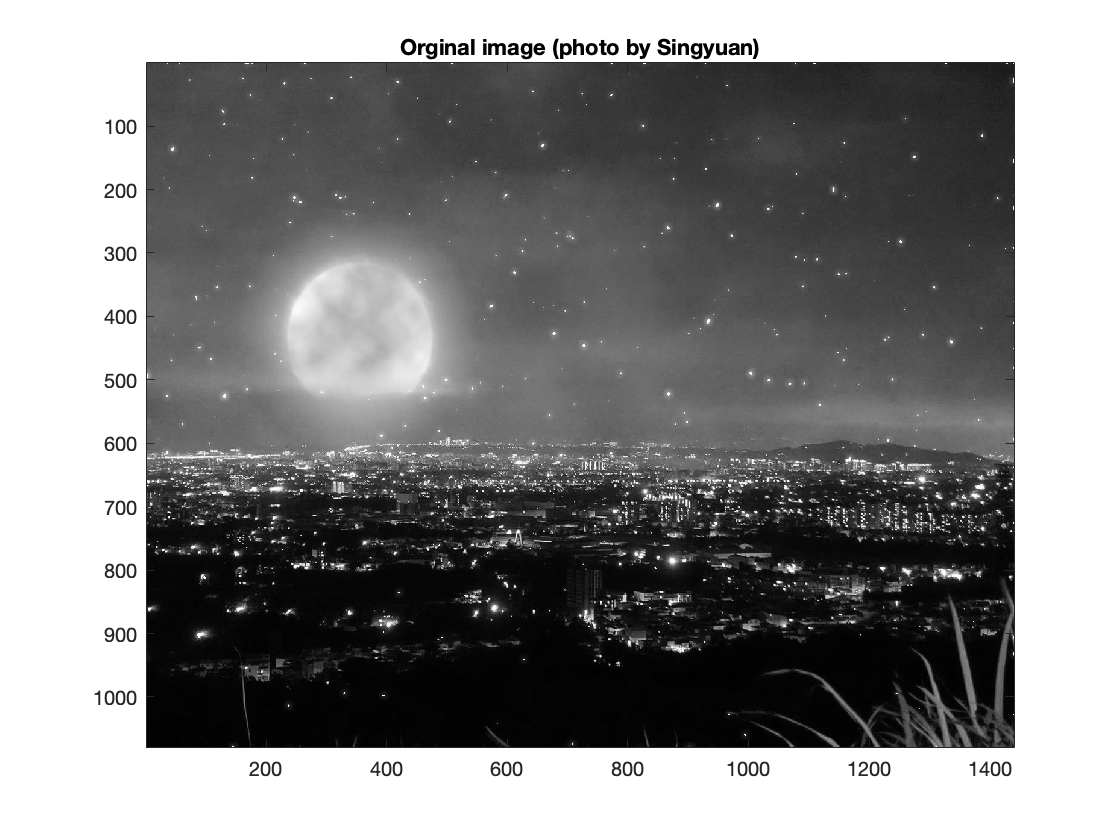

% X = imread('mountain.jpg');
% imshow(X)
% X = double(rgb2gray(X));
% X = X/255.0;
load('mountain_gray.mat')
mountain_gray;
figure
imagesc(mountain_gray);
colormap(gray);
title('Orginal image (photo by Singyuan)')

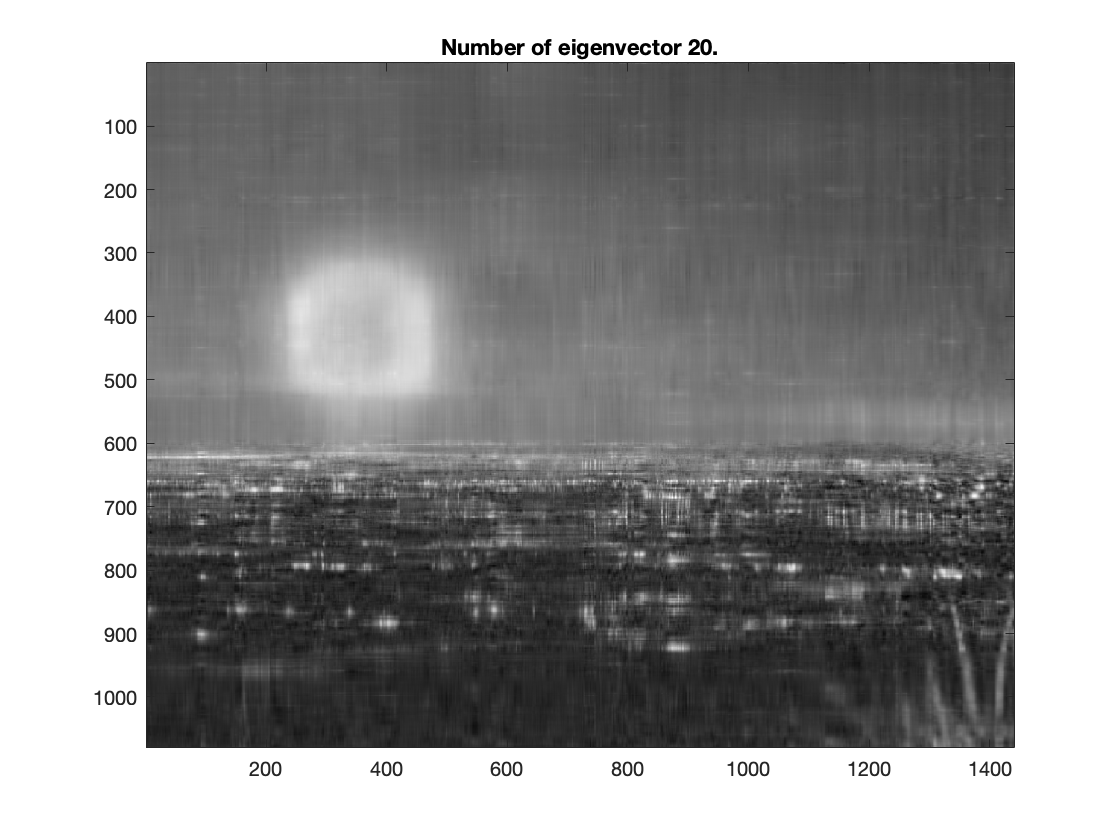

[U, S, V] = svd(mountain_gray);
figure
for i = 5:5:50
    imagesc(U(:, 1:i)*S(1:i, 1:i)*V(:, 1:i)');
    colormap(gray);
    title(['Number of eigenvector ', num2str(i), '.'])
    pause(0.5)
    drawnow
end

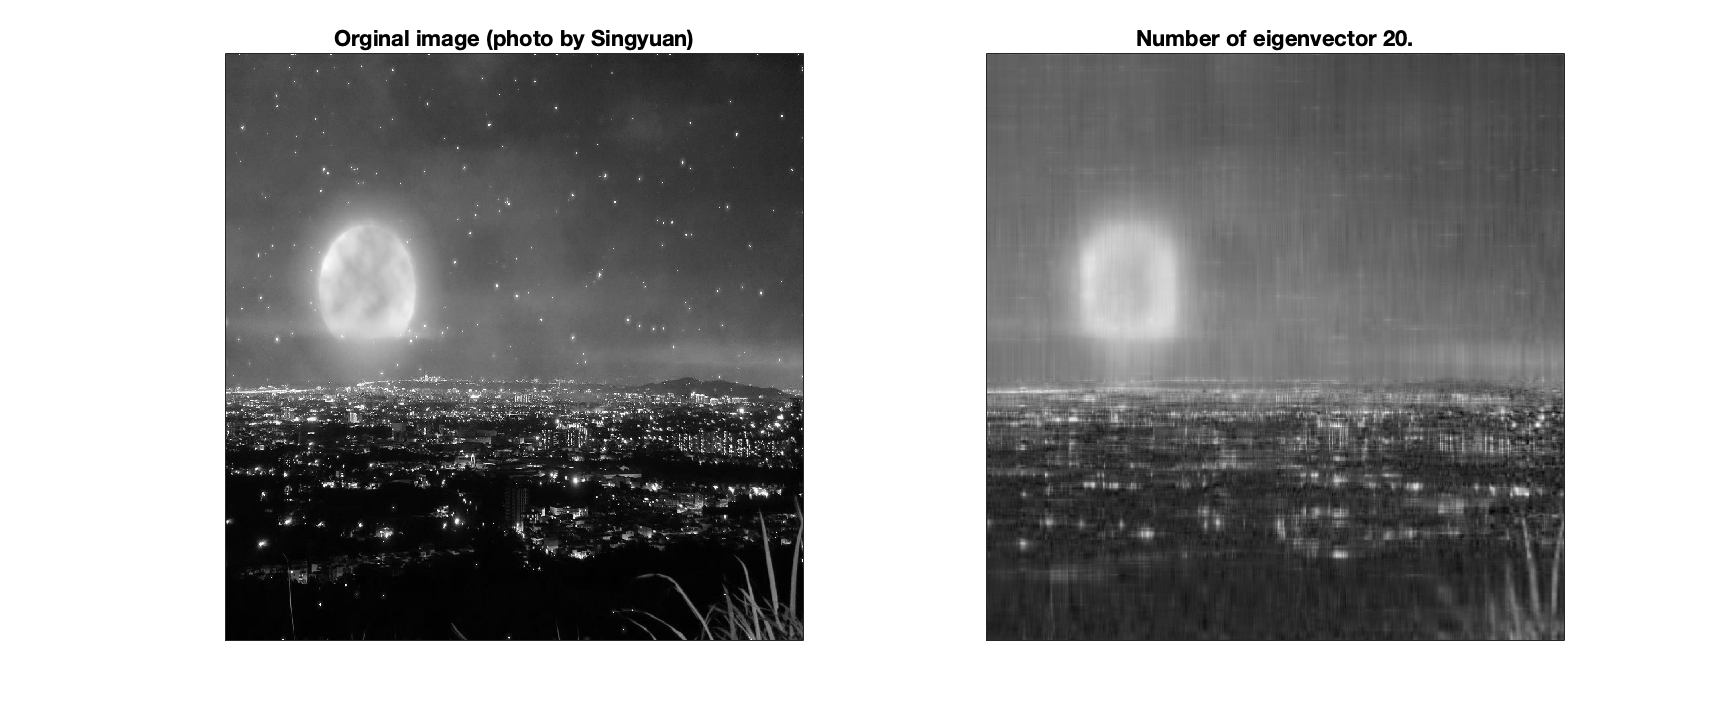

figure
set(gcf,'color','w','units','normalized','position',[0 0.5 0.6 0.4])
subplot(1, 2, 1)
imagesc(mountain_gray);
colormap(gray);
title('Orginal image (photo by Singyuan)')
set(gca,'xtick',[], 'ytick',[])
subplot(1, 2, 2)
imagesc(U(:, 1:20)*S(1:20, 1:20)*V(:, 1:20)');
colormap(gray);
title(['Number of eigenvector ', num2str(20), '.'])
set(gca,'xtick',[], 'ytick',[])